clc
clear all;
close all;
index = 100;

mdot_start = [7.5,7.4,7.4]; % lbm/s
mdot_end   = [7.5,7.5,7.6]; % lbm/s

alt_max(1) = 0;

for j = 1:length(mdot_start)
    [~, y_max] = FlightSim(mdot_start(j),mdot_end(j),index); % normal
    alt_max(j) = y_max *3.281;
end

BurnTime = 20

mass_end = 125.6407

BurnTime = 20.1342

mass_end = 125.6407

BurnTime = 20

mass_end = 125.6407

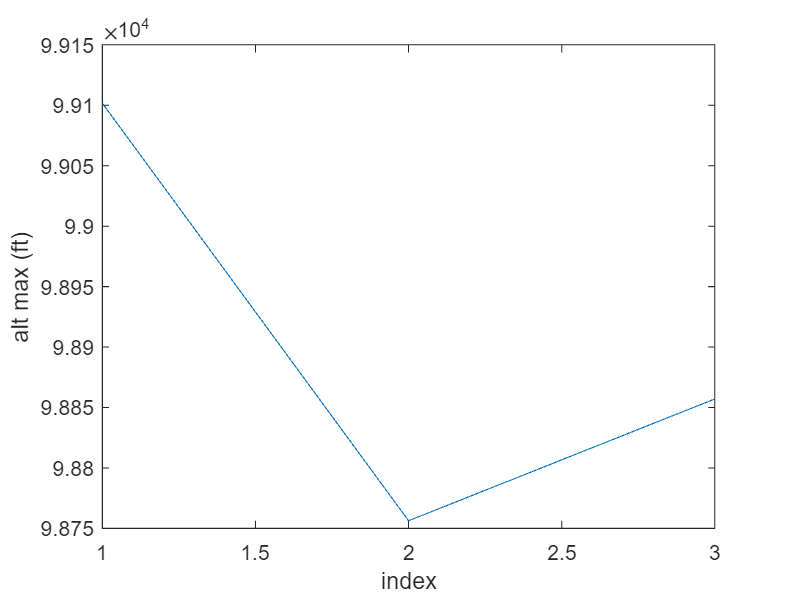

figure();
plot(1:1:length(mdot_start), alt_max)
xlabel("index")
ylabel("alt max (ft)")

function [y_burnout, y_max] = FlightSim(mdot_start,mdot_end, index)

Unit Check:


$$\dot{m}(\frac{slugs}{s}) = \frac{A^{\star}(in^2) * P_T(\frac{lbf}{in^2})}     {\sqrt{   R_{gas}({\frac{lbf * ft}{lbm* R^{\circ}})  * T_T(R^{\circ})  *  g_c (\frac{lbm*ft}{lbf*s^2})            }        }}*    \sqrt{\gamma} * (\frac{\gamma + 1}{2})^{\frac{-(\gamma +1)}{2 * (\gamma - 1)}}$$



$$R_{gas}({\frac{lbf * ft}{lbm* R^{\circ}}) = \frac{R_{Universal}({\frac{lbf * ft}{lbmol* R^{\circ}})}}{M(\frac{lbm}{lbmol})}$$


Equations:


$$\dot{m}= \frac{A^{\star} * P_T}     {\sqrt{   R_{gas}  * T_T  *  g_c             }        } *    \sqrt{\gamma} * (\frac{\gamma + 1}{2})^{\frac{-(\gamma +1)}{2 * (\gamma - 1)}}$$



$$R_{gas} = \frac{R_{Universal}}{M}$$


Constants:

mass_dry = 131.7; % lbm
mass_prop = 150; % lbm
m(1) = (mass_dry + mass_prop) /2.205; % kg

BurnTime = mass_prop/((mdot_start+mdot_end)/2) % s

R_universal = 1545.349; % lbf*ft/(lbmol*R)
Molar_Mass = 22.54; % (lbm/lbmol) (From RPA)
R_gas = R_universal/Molar_Mass; % lbf*ft/(lbm*R)
%P_Atmospheric = 12.3; % psi
Throat_ablation = 1; % (thou/s)
d_throat_nominal = 2.36;
%mdot_calc_lbm_nom = 7.5;  % lbm/s
time_span = linspace(0, BurnTime, index);
mdot_calc_lbm = (mdot_end - mdot_start)/(BurnTime)*(time_span)+mdot_start;
mdot_calc = mdot_calc_lbm ./ 32.174; % lbm/s

T_Chamber = 6229.0292; %(R)
g_c = 32.174; %(lbm ft/ lbf s^2)
gamma = 1.1787;
d_Exit = 7.5; %(in)
A_Exit = pi .* (1/4) .*(d_Exit).^2; %(in^2)

d_throat = linspace(d_throat_nominal, d_throat_nominal+BurnTime * Throat_ablation/1000, index); %(in)
A_throat = pi .* (1/4) .*(d_throat).^2; %(in^2)
P_Chamber = mdot_calc .* (sqrt(g_c * R_gas * T_Chamber))./ A_throat ./ sqrt(gamma) ./((gamma +1)  / 2)^(-(gamma +1)/(2* (gamma -1)));

Checking with RPA

R_gas_RPA = R_gas/778.169; % BTU/(lbm*R)
Prop_mass_difference = (mdot_calc_lbm(end) - mdot_calc_lbm(1)) * BurnTime;  % lbm

Exit Parameters

for i = 1:1:length(d_throat)
    [Exit_Mach(i), Exit_Pressure(i), Exit_Temperature(i)] = Nozzle(T_Chamber, P_Chamber(i), A_throat(i), A_Exit, gamma);
end
Sonic_Velocity = sqrt(gamma .* R_gas .* Exit_Temperature * g_c); % ft/s
Exit_Velocity = Exit_Mach .* Sonic_Velocity; % ft/s

OD = 8 /39.37; % m
A_cross = pi()/4*OD^2; % m^2
C_D = 0.7;

burnoutIndex = 0;
t(1) = 0;
y(1) = 0;
v(1) = 0;
Thrust(1) = 0;
FT(1) = 0;
FD(1) = 0;
FD(1) = 0;
dvdt(1) = 0;
deltaT = BurnTime/index;
for i = 1:(BurnTime/deltaT)+1000
    if y(i) < 44300
        P_A(i) = 101325*(1-0.0000225577*y(i))^5.25588;
    else
        P_A(i) = 0;
    end

    if y(i) < 11000 % troposphere
        T(i) = 15.04 - 0.00649*y(i);
    elseif y(i) < 25000 % lower stratosphere
        T(i) = -56.46;
    else % upper stratosphere
        T(i) = -131.21 + 0.00299*y(i);
    end

    density = P_A(i) / (287*(T(i)+273.1));

    if t(i) < BurnTime - deltaT/2
        Thrust(i) = mdot_calc_lbm(i) ./g_c .* Exit_Velocity(i) + ((Exit_Pressure(i)) - (P_A(i)/6895)) .*A_Exit; % lbf
        FT(i) = Thrust(i) *4.448; % N
        burnoutIndex = i+1;
    else
        FT(i) = 0;
    end
    FD(i) = 1/2*C_D*density*A_cross*v(i)^2; % N

    dvdt(i) = (FT(i)-FD(i))/m(i) - 9.81;

    v(i+1) = v(i) + deltaT*dvdt(i);
    y(i+1) = y(i) + deltaT*v(i);
    q(i+1) = 1/2*density*v(i)^2;
    if t(i) < BurnTime - deltaT/2
        m(i+1) = m(i) - (mdot_calc(i)/2.205)*deltaT;
    else
        m(i+1) = m(i);
    end
    t(i+1) = t(i) + deltaT;

    if v(i+1) < 0
        break;
    end
end

% figure();
% plot(time_span, Thrust)
% xlabel("Time (sec)")
% ylabel("Thrust (lbf)")

% figure();
% plot(t,y/1000,'b')
% hold on;
% plot(t(burnoutIndex),y(burnoutIndex)/1000,'rx')
% xlabel("Time (sec)")
% ylabel("Altitude (km)")

% figure();
% plot(t,v/1000,'b')
% hold on;
% plot(t(burnoutIndex),v(burnoutIndex)/1000,'rx')
% xlabel("Time (sec)")
% ylabel("Velocity (km/s)")

[maxQ,maxQi] = max(q);

% figure();
% plot(t(1:end-1),FD/4.448,'b')
% hold on;
% plot(t(burnoutIndex),FD(burnoutIndex)/4.448,'rx')
% plot(t(maxQi),FD(maxQi)/4.448,'gx')
% xlabel("Time (sec)")
% ylabel("Force Drag (N)")

% figure();
% plot(t(1:end-1),dvdt,'b')
% hold on;
% plot(t(burnoutIndex),dvdt(burnoutIndex),'rx')
% plot(t(maxQi),dvdt(maxQi),'gx')
% xlabel("Time (sec)")
% ylabel("dvdt")

mass_end = m(end)
% maxQ = maxQ/6895 % psi
y_burnout = y(burnoutIndex); % km
y_max = y(end); % km

% FT_total = trapz(t(1:burnoutIndex),FT(1:burnoutIndex)) /BurnTime
% FD_total = trapz(t(1:burnoutIndex),FD(1:burnoutIndex)) /BurnTime
% dvdt_total = trapz(t(1:burnoutIndex),dvdt(1:burnoutIndex)) /BurnTime
end

function [Exit_Mach, Exit_Pressure, Exit_Temperature] = Nozzle(Total_Temperature, Total_Pressure, Throat_Area, Exit_Area, Specific_Heat_Ratio)
    syms Ma;
    Ma_exit = vpasolve(Exit_Area/Throat_Area == (1/Ma) *((1+((Specific_Heat_Ratio-1)/2)*(Ma^2))/(1+(Specific_Heat_Ratio-1)/2))^((Specific_Heat_Ratio+1)/(2*(Specific_Heat_Ratio-1))), Ma, 3);
    if(length(Ma_exit) <2)
        Exit_Mach = double(Ma_exit(1));
    else 
        Exit_Mach = double(Ma_exit(2));
    end
    Exit_Pressure = double(Total_Pressure/(1+((Specific_Heat_Ratio-1)/2)*Exit_Mach^2)^(Specific_Heat_Ratio/(Specific_Heat_Ratio-1)));
    Exit_Temperature = double(Total_Temperature/(1+((Specific_Heat_Ratio-1)/2)*Exit_Mach^2));
end